# 로봇 비전 HW1

due date : 10월 13일 23:59

코드 작성한 후 본인의 Github에 업로드하고 Repository URL을 적으세요. 

GitHub URL : 

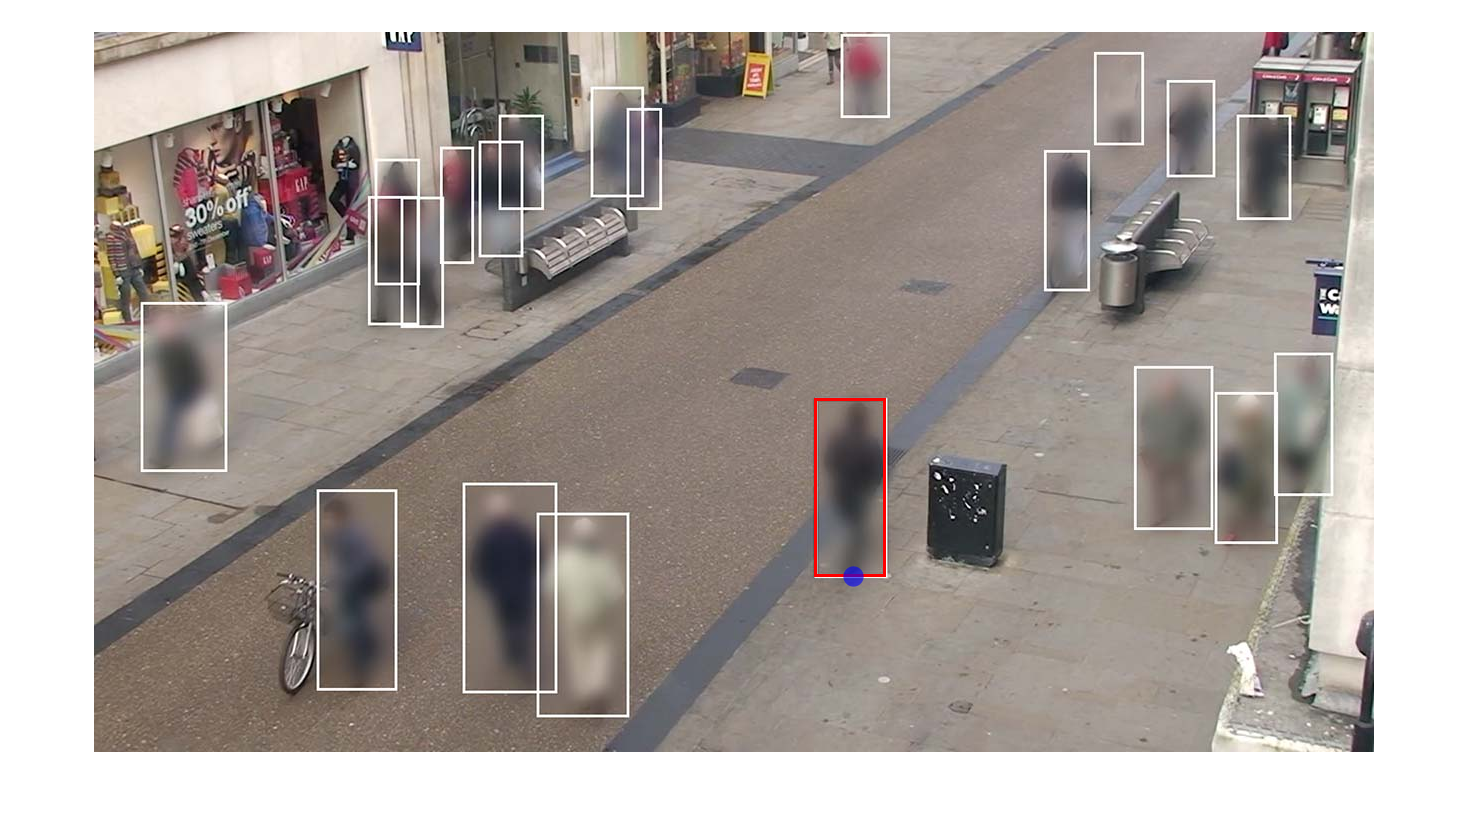

%image 정보 불러오기
img = imread("background.jpg");
img_rec = insertShape(img, 'Rectangle', [722 368 70 177], 'Color', "red", 'LineWidth', 3);      % 사각형 그리기
img_rec = insertShape(img_rec, 'FilledCircle', [760 545 10], 'Color', "blue", 'LineWidth', 10); 
figure(2);
imshow(img_rec);

- 임의의 카메라의 설치 위치와 각도에 따라 사람의 발(파란 점)의 3차원 좌표를 구하는 Matlab 코드를 작성하세요. 

- World Coordinate 원점에 대한 카메라의 위치는 다음과 같다.

- 카메라의 위치는 R과 t로 주어진다. 

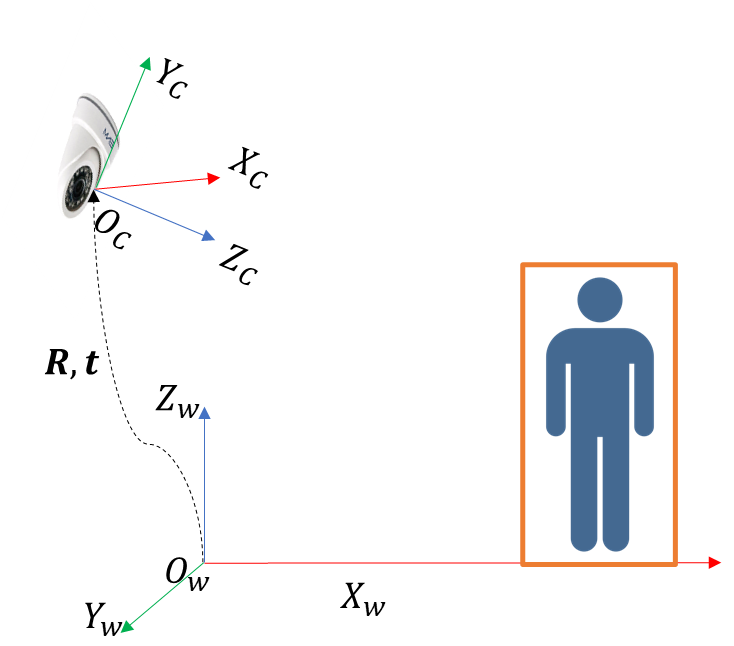

- f_x = 1000 pixel, f_y = 1000 pixel

- c_x = 640 pixel, c_y = 480 pixel

- 이미지 size : 1280*720

- 이미지 상 파란 점의 위치 : (760, 545)

% Intrinsic Parameters
fx = 1000;
fy = 1000;
cx = 640;
cy = 480;

% 파란점의 픽셀 위치
u = 760;
v = 545;

% 임의의 카메라 설치 위치
theta_x = pi/2 - pi/6;  % x축 각도
theta_y = -pi/2;        % y축 각도
theta_z = pi/2;         % z축 각도

% 위치
tx = 0;
ty = -5;
tz = 0.2;

% Camera Matrix?
camera_matrix = [fx,0,cx; 0,fy,cy; 0,0,1];

% Rotation Matrix?
r1 = [0,0,1];
r2 = [-1,0,0];
r3 = [0,1,0];
Rotation = [r1 ;r2 ;r3].';

% Translation Matrix?
Translation = [tx, ty, tz].';

% World Coordinate 좌표 값?

syms Xw;
syms Yw;
syms s;
Zw = 0;

image_pixel = [u,v,1].';

% #### camera calibration ####
% s * image_pixel == camera_matrix * [Rotation Translation] * [Xw, Yw, Zw,1].'

s * inv(camera_matrix) * image_pixel == [Rotation Translation] * [Xw, Yw, Zw, 1].'

$$ans = \left(\begin{array}{c} \frac{3\,s}{25}=-\mathrm{Yw}\\ \frac{13\,s}{200}=-5\\ s=\mathrm{Xw}+\frac{1}{5} \end{array}\right)$$

s = -5 * (200/13);
Yw = (3/25) * (-s);
Xw = s-(1/5);

World_coordinate = [Xw, Yw, Zw, 1].';
World_coordinate

World_coordinate =   -77.1231
    9.2308
         0
    1.0000
